restoredefaultpath; 
clear; clc; close all 
format long 
addpath( "materialProperties/7 Groups/" );
addpath( "materialProperties/2 Groups/" );
addpath( "setupCrossSections/" );
addpath( "MATLAB2Tex/");

# Test A 

## Matrix Solution 

[Sigma_t, ~, Sigma_s, Sigma_f, nu, chi] = getMOX87();
L = Sigma_t .* eye( 7 ) - Sigma_s

L =    0.051541000000000                   0                   0                   0                   0                   0                   0
  -0.042046000000000   0.006302000000000                   0                   0                   0                   0                   0
  -0.000008697200000  -0.001646300000000   0.038715000000000                   0                   0                   0                   0
  -0.000000005193800  -0.000000002600600  -0.002474900000000   0.138153000000000  -0.000185970000000                   0                   0
                   0                   0                   0  -0.005433000000000   0.216983000000000  -0.002391600000000                   0
                   0                   0                   0                   0  -0.008397300000000   0.673414000000000  -0.008968100000000
                   0                   0                   0                   0  -0.000000008928000  -0.012322000000000   0.699138000000000


P = chi .* transpose( nu .* Sigma_f )

P =    0.014807103672430   0.002786405010744   0.017330442713030   0.065992896604613   0.032513194255248   0.632002566707482   0.728595904659667
   0.010370589049616   0.001951540418132   0.012137883505158   0.046220059372890   0.022771568550528   0.442641521436058   0.510293496798259
   0.000008539566551   0.000001606978080   0.000009994828981   0.000038059484484   0.000018751039520   0.000364489105931   0.000420196505305
   0.000000002962126   0.000000000557414   0.000000003466914   0.000000013201722   0.000000006504187   0.000000126430613   0.000000145753881
                   0                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0                   0                   0                   0


A = inv( L ) * P 

A = 1.0e+02 *

   0.002872878615555   0.000540619120844   0.003362457599393   0.012803961235640   0.006308219525280   0.122621324131756   0.141362392010180
   0.035623444107548   0.006703629916906   0.041694180780014   0.158768001879185   0.078221371574932   1.520493717677628   1.752881323777000
   0.001517687141926   0.000285598801127   0.001776322409252   0.006764089240610   0.003332512418077   0.064778513771206   0.074679063551154
   0.000027190055369   0.000005116632408   0.000031823623807   0.000121181734952   0.000059703475547   0.001160536534513   0.001337909386444
   0.000000680900724   0.000000128132093   0.000000796935799   0.000003034665799   0.000001495110590   0.000029062469940   0.000033504288896
   0.000000008492651   0.000000001598149   0.000000009939918   0.000000037850389   0.000000018648023   0.000000362486637   0.000000417887985
   0.000000000149688   0.000000000028168   0.000000000175197   0.000000000667135   0.000000000328682   0.000000006389039   0.00000000736552

k = eig( A )

k =   1.147587763941254 + 0.000000000000000i
  0.000000000000000 + 0.000000000000000i
  0.000000000000000 + 0.000000000000000i
 -0.000000000000000 + 0.000000000000000i
 -0.000000000000000 + 0.000000000000000i
 -0.000000000000000 + 0.000000000000000i
 -0.000000000000000 - 0.000000000000000i


k_eff = max( k )

k_eff =    1.147587763941254


## Numeric Solution 

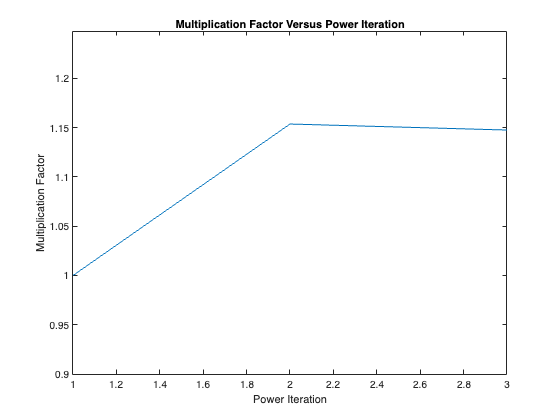

clear;
texFile = "TestA.txt";
figFolder = "figFolderA";
epPhi = 1e-5;
epk = 1e-5; 
h = 1.08 / 10;

[Sigma_t, Sigma_tr, Sigma_s, Sigma_f, nu, chi] = getTestA();
[phi, current, k, Iterations, kplot, fluxMesh, currentMesh, fluxResid, currentResid] = solveDiffusion(Sigma_t, Sigma_tr, Sigma_s, Sigma_f, nu, chi, h, epPhi, epk );
fig2Tex( kplot, "k_A", texFile, "Multiplication Factor versus Iterations", 'w', figFolder )

kands = table( k, Iterations ) 

kands = 1×2 table
           k           Iterations
    _______________    __________

    1.1475877749248        3     


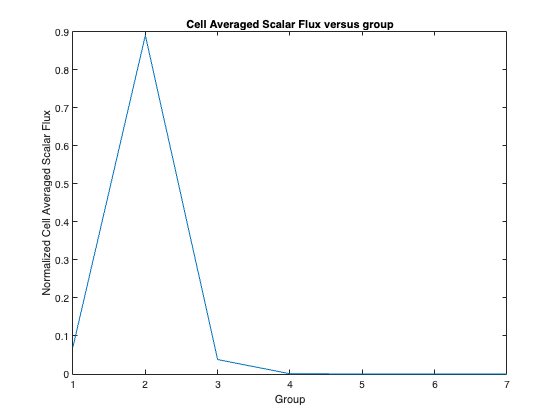

table2Tex( kands, texFile, "Multiplication Factor and Number of Power Iterations", "long", 'a', 0 );
f = figure(); 
    plot( 1:numel( phi( :, 5 ) ), phi( :, 5 ))
    title( "Cell Averaged Scalar Flux versus group")
    xlabel( "Group")
    ylabel( "Normalized Cell Averaged Scalar Flux")
fig2Tex( f, "spec_A", texFile, "Cell Averaged Scalar Flux versus group" , 'a', figFolder )

fluxTable = array2table( [phi( :, 1 ), phi( :, 5 )], "VariableNames", {'\(\phi\) at x = 0', '\(\Bar{\phi}_5\)'})

fluxTable = 7×2 table
     \(\phi\) at x = 0        \(\Bar{\phi}_5\)  
    ____________________    ____________________

      0.0717468294374727      0.0717468294374727
         0.8896544234488         0.8896544234488
      0.0379024856538149       0.037902485653815
     0.00067904076333435     0.00067904076333435
    1.70048592771098e-05    1.70048592771098e-05
    2.12098933115585e-07    2.12098933115585e-07
    3.73836763733893e-09    3.73836763733893e-09


table2Tex( fluxTable, texFile, "Normalized Cell Averaged Scalar Flux at \( \Bar{x}_5 \)", 'long', 'a', 0 )

# Test B

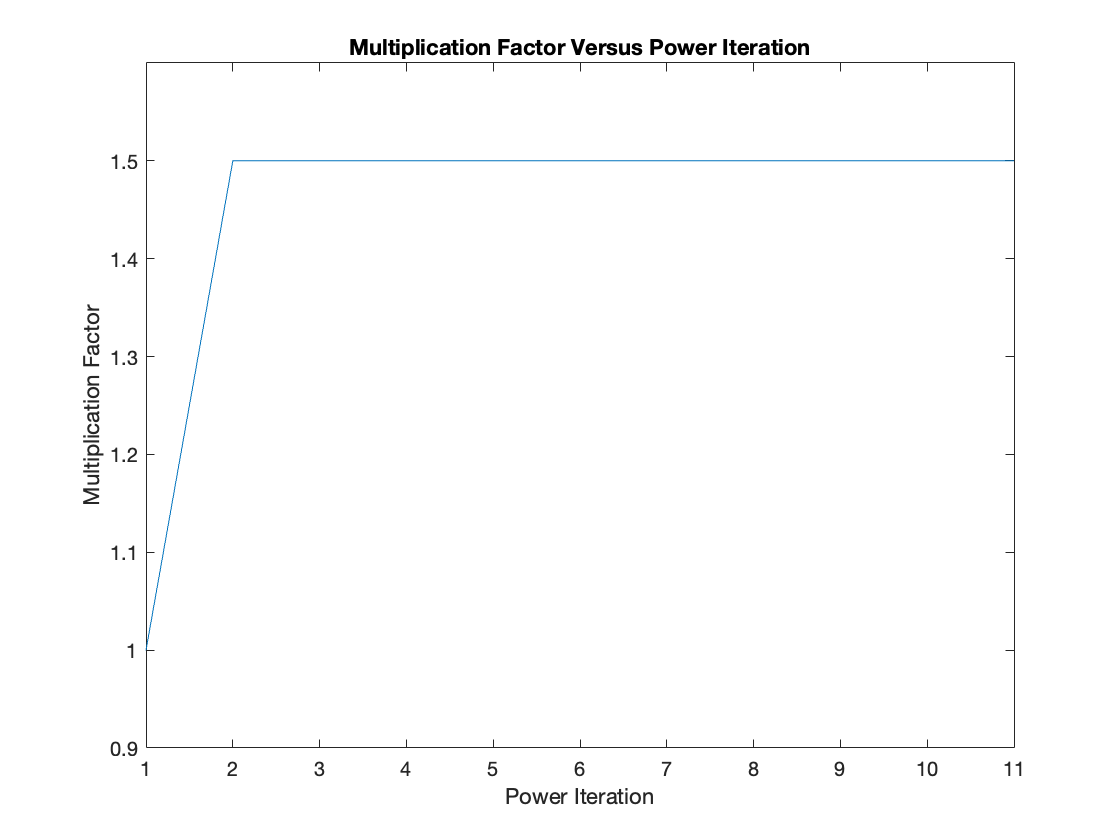

texFile = "TestB.txt";
figFolder = "figFolderB";
epPhi = 1e-5;
epk = 1e-5; 
h = 0.15625;
[Sigma_t, Sigma_tr, Sigma_s, Sigma_f, nu, chi] = getTestB();
[phi, current, k, Iterations, kplot, fluxMesh, currentMesh, fluxResid, currentResid] = solveDiffusion(Sigma_t, Sigma_tr, Sigma_s, Sigma_f, nu, chi, h, epPhi, epk );
fig2Tex( kplot, "k_B", texFile, "Multiplication Factor versus Iterations", 'w', figFolder )

kands = table( k, Iterations ) 

kands = 1×2 table
     k     Iterations
    ___    __________

    1.5        11    


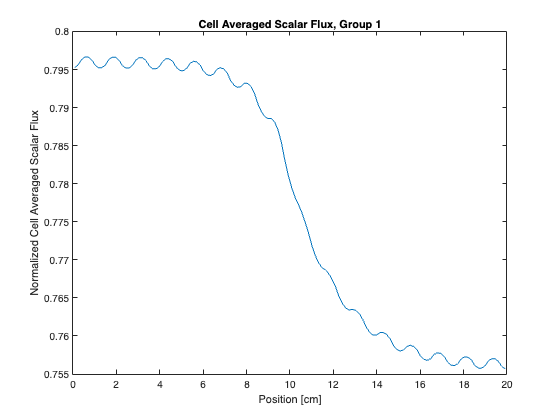

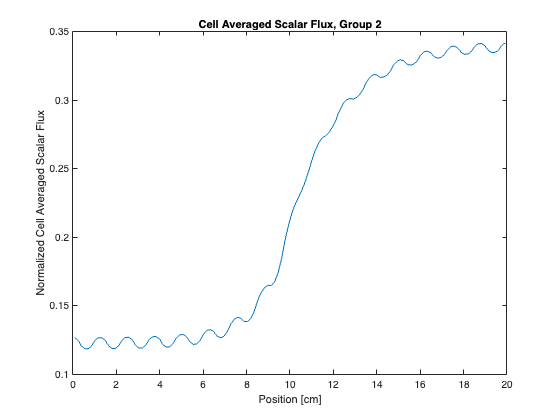

table2Tex( kands, texFile, "Multiplication Factor and Number of Power Iterations", "long", 'a', 0 );
[ Ng , ~ ] = size( phi );
for i = 1:Ng
    f = figure();
        plot( fluxMesh, phi( i, : ) )
        title( sprintf("Cell Averaged Scalar Flux, Group %d", i ) )
        xlabel( "Position [cm]")
        ylabel( "Normalized Cell Averaged Scalar Flux")
    fig2Tex( f, sprintf( "fluxB_%d", i ), texFile, sprintf( "Cell Averaged Scalar Flux versus position in group %d", i ) , 'a', figFolder )    
end

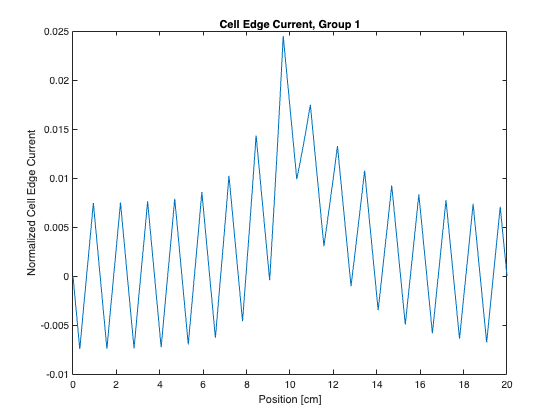

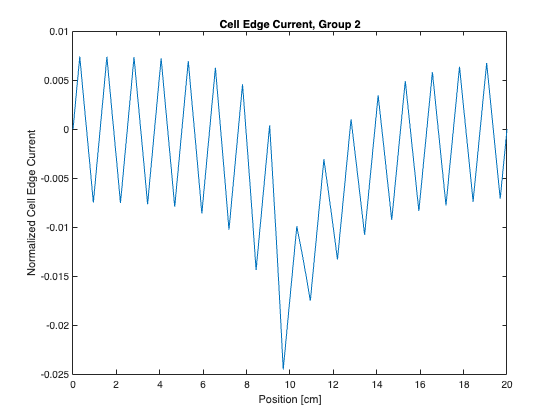

for i = 1:Ng
    f = figure();
        plot( currentMesh, current( i, : ) )
        title( sprintf("Cell Edge Current, Group %d", i ) )
        xlabel( "Position [cm]")
        ylabel( "Normalized Cell Edge Current")
    fig2Tex( f, sprintf( "currB_%d", i ), texFile, sprintf( "Cell Edge Current versus position in group %d", i ) , 'a', figFolder )    
end 

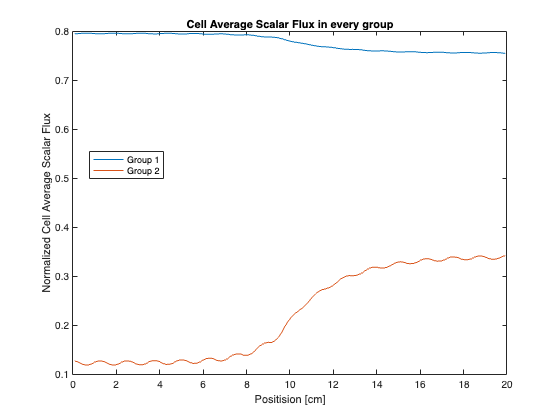

[ Ng , ~ ] = size( phi );

names = cell( Ng, 1 );
for i = 1:Ng 
    names{ i } = sprintf( "Group %d", i);
end 
f = figure(); 
    plot( fluxMesh, phi );
    title( "Cell Average Scalar Flux in every group" )
    xlabel( "Positision [cm]")
    ylabel( "Normalized Cell Average Scalar Flux")
    legend( names, 'location', 'best')
    fig2Tex( f, "fluxB_all", texFile, "Cell Average Flux versus position for all groups" , 'a', figFolder )    

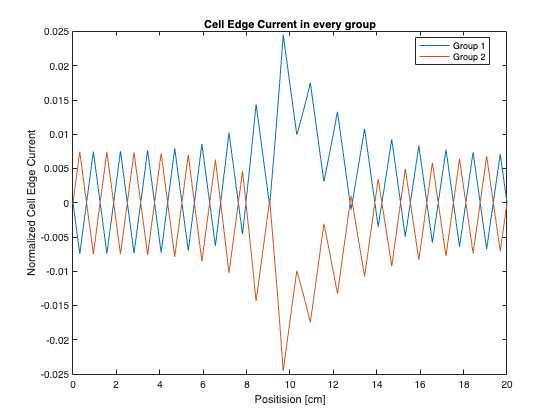


f = figure(); 
    plot( currentMesh, current );
    title( "Cell Edge Current in every group" )
    xlabel( "Positision [cm]")
    ylabel( "Normalized Cell Edge Current") 
    legend( names, 'location', 'best')
    fig2Tex( f, "currB_all", texFile, "Cell Edge Current versus position for all groups" , 'a', figFolder )    

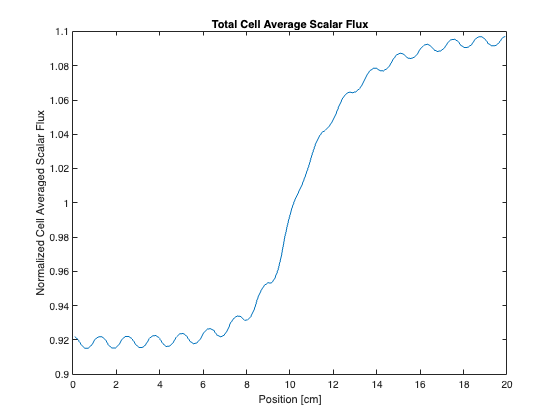


f = figure();
    plot( fluxMesh, sum( phi, 1 ) )
    title( "Total Cell Average Scalar Flux")
    ylabel( "Normalized Cell Averaged Scalar Flux")
    xlabel( "Position [cm]")
    fig2Tex( f, "fluxB_sum", texFile, "Total scalar flux versus position" , 'a', figFolder )    

table4 = array2table( phi( :, 4 ), 'VariableNames',{'\( \Bar{\phi}_{4}\)'});
table124 = array2table( phi( :, 124 ), 'VariableNames',{'\( \Bar{\phi}_{124}\)'});
fluxTable = [table4, table124]

fluxTable = 2×2 table
    \( \Bar{\phi}_{4}\)    \( \Bar{\phi}_{124}\)
    ___________________    _____________________

     0.796635787920016       0.757007950916044  
     0.118462135138021       0.334638076754114  


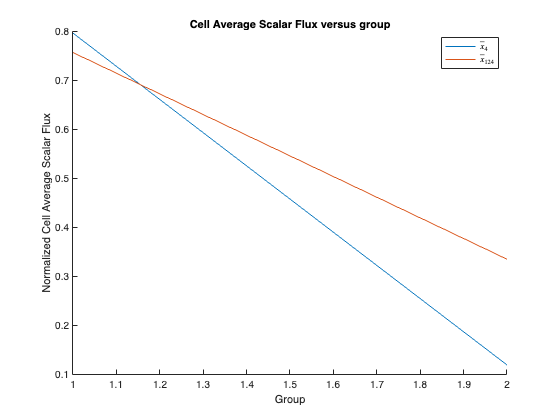

table2Tex( fluxTable, texFile, "Cell Average Scalar Flux versus group \(\Bar{x}_4\) and \(\Bar{x}_{124}\)", 'long', 'a', 0 )
f = figure();
hold on 
    plot( 1:Ng, table4.Variables )
    plot( 1:Ng, table124.Variables )
    title( "Cell Average Scalar Flux versus group")
    xlabel( "Group")
    ylabel( "Normalized Cell Average Scalar Flux")
    legend( {'\( \bar{x}_4 \)', '\( \bar{x}_{124} \)'}, 'location', 'best', 'Interpreter','latex')
hold off 
fig2Tex( f, "fluxB_some", texFile, "Cell Average Flux versus group at \(\Bar{x}_4\) and \(\Bar{x}_{124}\)" , 'a', figFolder )    

table10 = array2table( current( :, currentMesh == 10 ), "VariableNames", {'J at x = 10'} )

table10 = 2×1 table
        J at x = 10    
    ___________________

     0.0172152369757731
    -0.0172147530455268


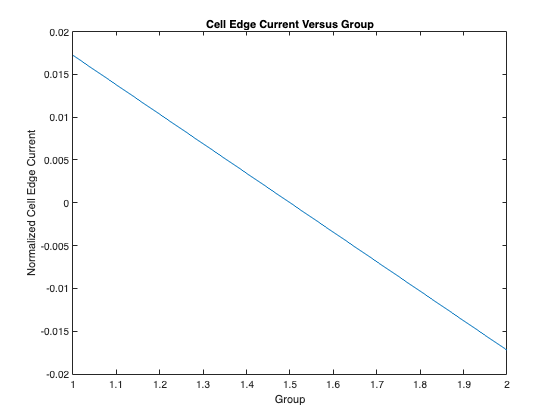

table2Tex( table10, texFile, "Cell Edge Current versus group at x = 10", 'long', 'a', 0 )
f = figure();
    plot( 1:Ng, table10.Variables )
    title( "Cell Edge Current Versus Group")
    xlabel( "Group")
    ylabel( "Normalized Cell Edge Current")
fig2Tex( f, "currB_some", texFile, "Cell Edge Current versus group at x = 10" , 'a', figFolder )    

# Test C

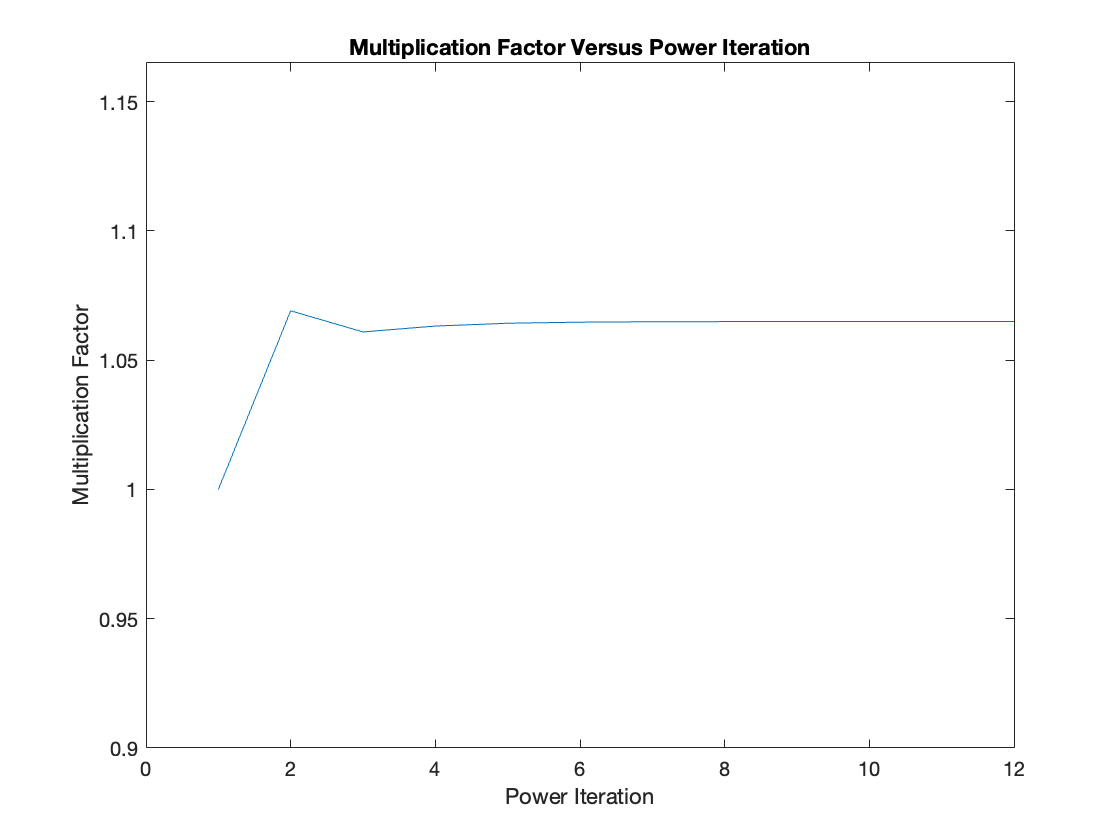

texFile = "TestC.txt";
figFolder = "figFolderC";
epPhi = 1e-5;
epk = 1e-5; 
h = 0.09;
[Sigma_t, Sigma_tr, Sigma_s, Sigma_f, nu, chi] = getTestC();
[phi, current, k, Iterations, kplot, fluxMesh, currentMesh, fluxResid, currentResid] = solveDiffusion(Sigma_t, Sigma_tr, Sigma_s, Sigma_f, nu, chi, h, epPhi, epk );
fig2Tex( kplot, "k_C", texFile, "Multiplication Factor versus Iterations", 'w', figFolder )

kands = table( k, Iterations ) 

kands = 1×2 table
           k            Iterations
    ________________    __________

    1.06495756438363        12    


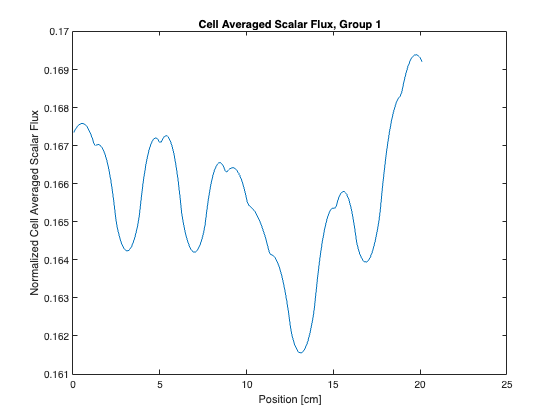

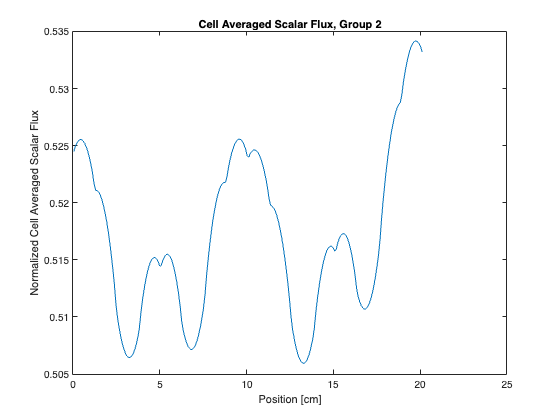

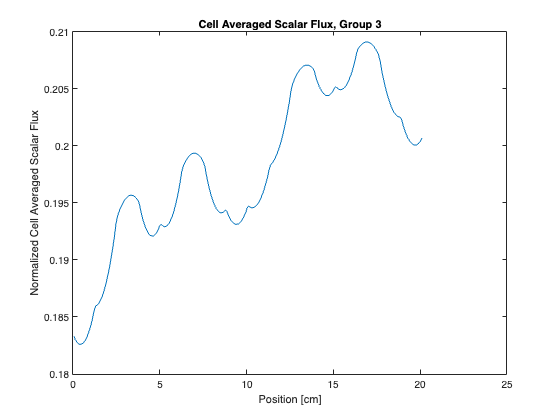

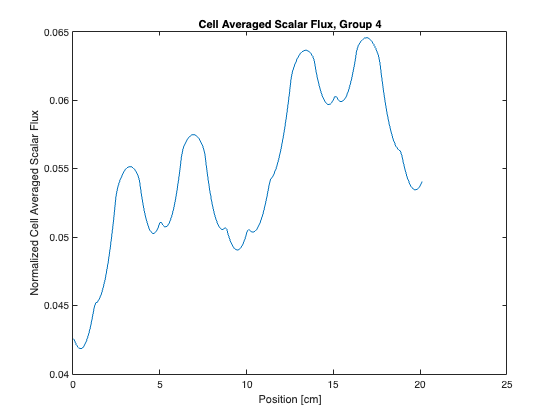

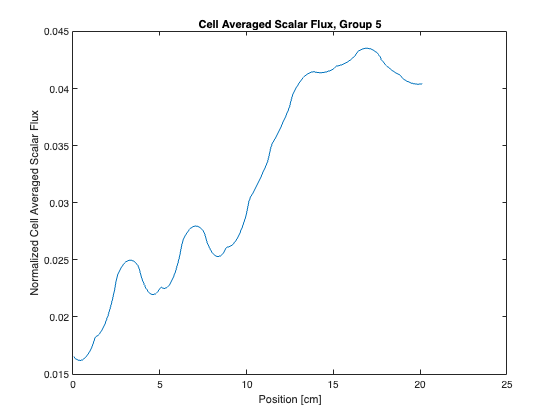

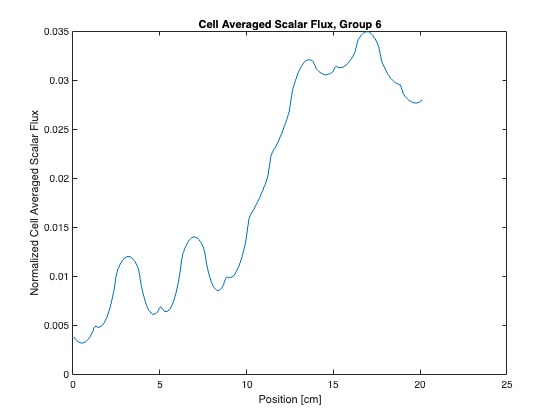

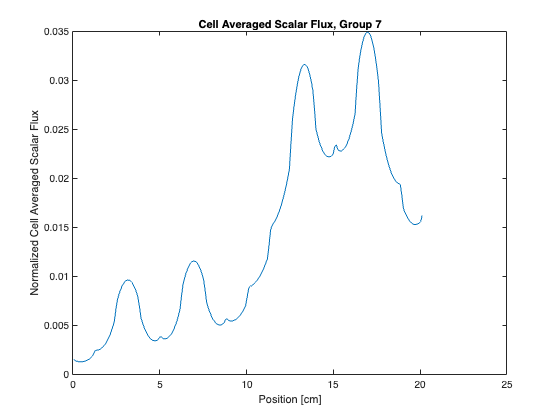

table2Tex( kands, texFile, "Multiplication Factor and Number of Power Iterations", "long", 'a', 0 );
[ Ng , ~ ] = size( phi );
for i = 1:Ng
    f = figure();
        plot( fluxMesh, phi( i, : ) )
        title( sprintf("Cell Averaged Scalar Flux, Group %d", i ) )
        xlabel( "Position [cm]")
        ylabel( "Normalized Cell Averaged Scalar Flux")
    fig2Tex( f, sprintf( "fluxC_%d", i ), texFile, sprintf( "Cell Averaged Scalar Flux versus position in group %d", i ) , 'a', figFolder )    
end

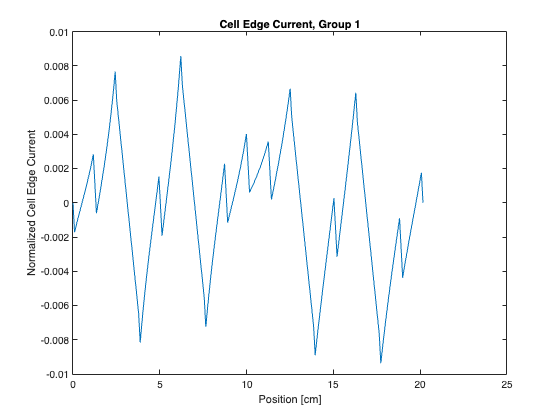

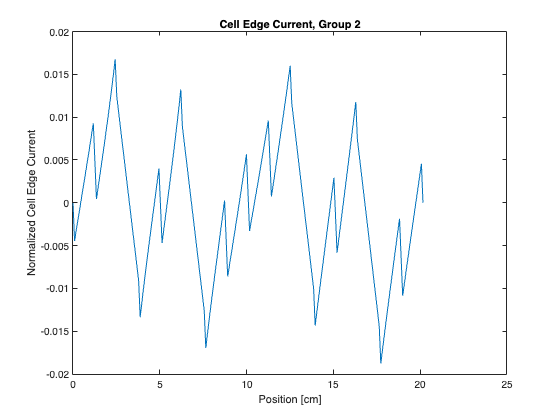

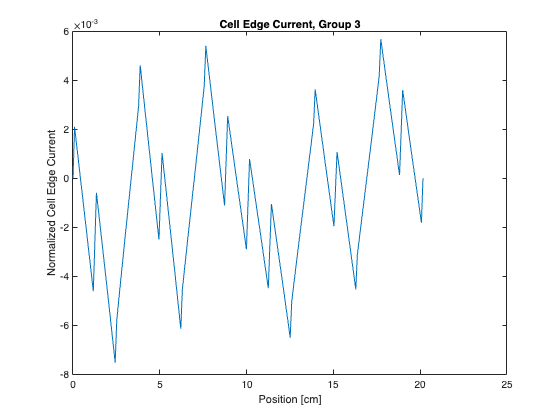

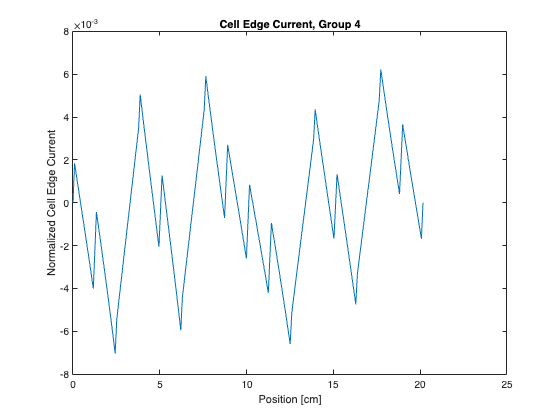

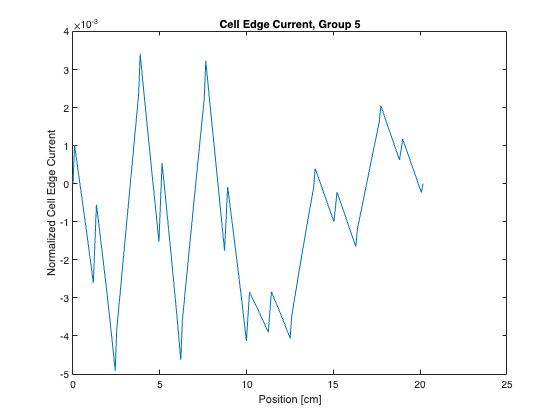

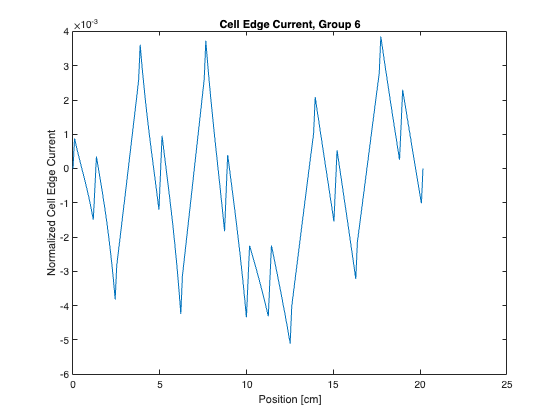

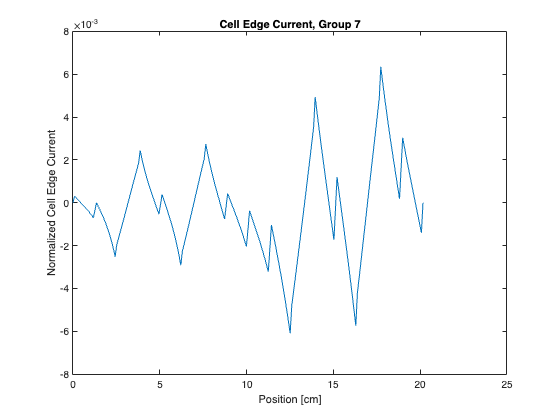

for i = 1:Ng
    f = figure();
        plot( currentMesh, current( i, : ) )
        title( sprintf("Cell Edge Current, Group %d", i ) )
        xlabel( "Position [cm]")
        ylabel( "Normalized Cell Edge Current")
    fig2Tex( f, sprintf( "currC_%d", i ), texFile, sprintf( "Cell Edge Current versus position in group %d", i ) , 'a', figFolder )    
end 

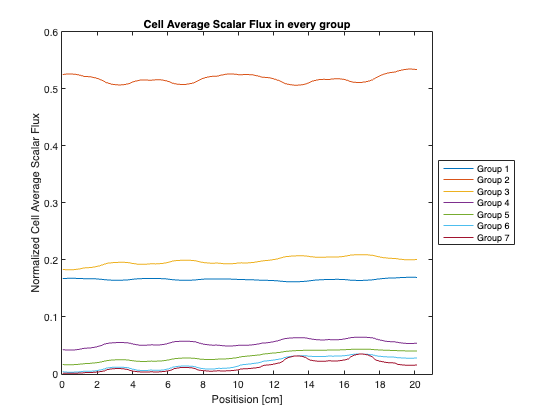

[ Ng , ~ ] = size( phi );

names = cell( Ng, 1 );
for i = 1:Ng 
    names{ i } = sprintf( "Group %d", i);
end 
f = figure(); 
    plot( fluxMesh, phi );
    title( "Cell Average Scalar Flux in every group" )
    xlabel( "Positision [cm]")
    ylabel( "Normalized Cell Average Scalar Flux")
    legend( names, 'location', 'eastoutside')
    xlim([ 0, 21]);
    fig2Tex( f, "fluxC_all", texFile, "Cell Average Flux versus position for all groups" , 'a', figFolder )    

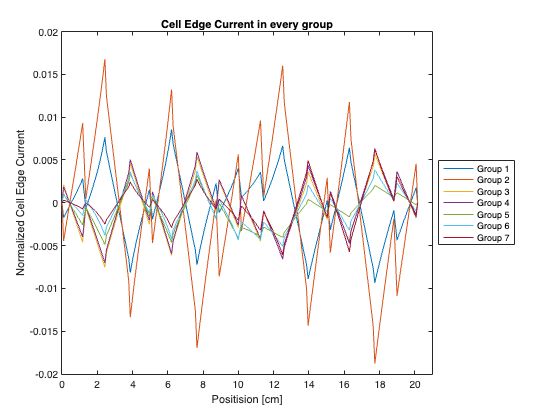


f = figure(); 
    plot( currentMesh, current );
    title( "Cell Edge Current in every group" )
    xlabel( "Positision [cm]")
    ylabel( "Normalized Cell Edge Current") 
    legend( names, 'location', 'eastoutside')
    xlim([ 0, 21]);
    fig2Tex( f, "currC_all", texFile, "Cell Edge Current versus position for all groups" , 'a', figFolder )    

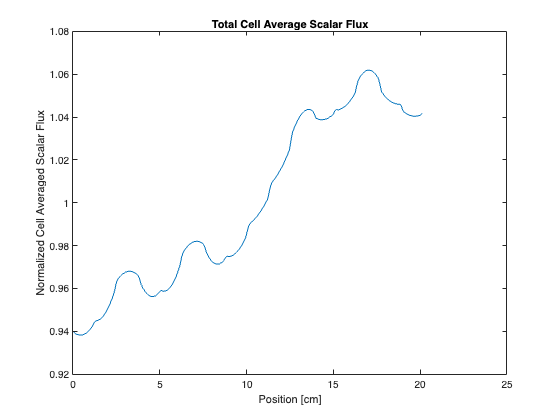

f = figure();
    plot( fluxMesh, sum( phi, 1 ) )
    title( "Total Cell Average Scalar Flux")
    ylabel( "Normalized Cell Averaged Scalar Flux")
    xlabel( "Position [cm]")
    fig2Tex( f, "fluxC_sum", texFile, "Total scalar flux versus position" , 'a', figFolder )    

table7 = array2table( phi( :, 7 ), 'VariableNames', {'\( \Bar{\phi} at \Bar{x}_7 \)'} );
table214 = array2table( phi( :, 214 ), 'VariableNames', {'\( \Bar{\phi} at \Bar{x}_{214} \)'} );
fluxTable = [table7, table214]

fluxTable = 7×2 table
    \( \Bar{\phi} at \Bar{x}_7 \)    \( \Bar{\phi} at \Bar{x}_{214} \)
    _____________________________    _________________________________

           0.167579548981469                 0.168959911429612        
           0.525416693649864                  0.53217317167335        
            0.18270819279943                 0.200920852435996        
          0.0419598617249831                0.0545084866466915        
          0.0162738118994245                 0.040666299693411        
         0.00318546350195397                0.0281939920578439        
         0.00126743268457341                0.0161506240922804        


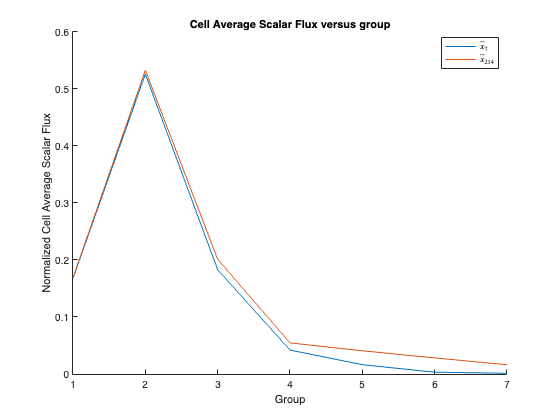

table2Tex( fluxTable, texFile, "Cell Average Scalar Flux at \( \Bar{x}_7 and \Bar{x}_{214} \)", 'long', 'a', 0 )
f = figure(); 
hold on 
    plot( 1:Ng, table7.Variables )
    plot( 1:Ng, table214.Variables )
    title( "Cell Average Scalar Flux versus group")
    xlabel( "Group")
    ylabel( "Normalized Cell Average Scalar Flux")
    legend( {'\( \bar{x}_7 \)', '\( \bar{x}_{214} \)'}, 'location', 'best', 'Interpreter', 'latex')
hold off 
fig2Tex( f, "fluxC_some", texFile, "Cell Average Flux versus group at \(\Bar{x}_7\) and \(\Bar{x}_{214}\)" , 'a', figFolder )    

table108 = array2table( current( :, currentMesh == 10.8 ), 'VariableNames',{'J at \(x = 10.8\)'})

table108 = 7×1 table
     J at \(x = 10.8\)  
    ____________________

     0.00212617353714679
     0.00409575382596179
    -0.00228089542552279
    -0.00206685433280316
    -0.00345250080485445
    -0.00339364554480409
    -0.00191934949823506


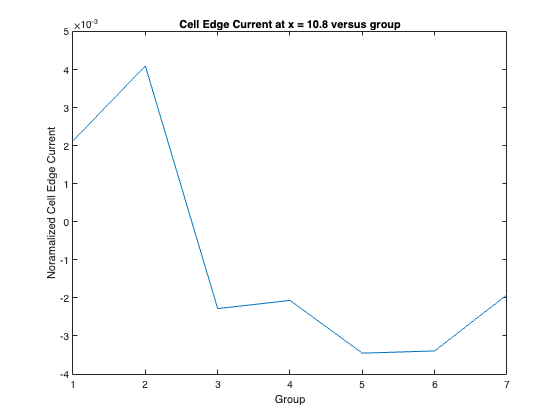

table2Tex( table108, texFile, "Cell Edge Current at \( x = 10.8 \)", 'long', 'a', 0 )
f = figure();
    plot( 1:Ng, table108.Variables )
    title( "Cell Edge Current at x = 10.8 versus group" )
    xlabel( "Group")
    ylabel( "Noramalized Cell Edge Current")
fig2Tex( f, "currC_some", texFile, "Cell Edge Current at x = 10.8 versus group" , 'a', figFolder )    